## Definición de Problema

clear;
CostFunc = "Rastrigin";

PosMax = 6;                             % Valor máximo que pueden adquirir las variables X1 y X2
PosMin = -PosMax;                       % Valor mínimo que pueden adquirir las variables X1 y X2
VarDims = 2;                            % No. Variables desconocidas (Varibles de decisión). Dims de posición de partículas

VelMax = 0.2*(PosMax - PosMin);
VelMin = -VelMax;

[MeshX, MeshY] = meshgrid(PosMin:0.1:PosMax, PosMin:0.1:PosMax);
Mesh2D = [reshape(MeshX, [], 1) reshape(MeshY, [], 1)];
Altura = reshape(CostFunction(Mesh2D,CostFunc), size(MeshX, 1), size(MeshX, 2));
MaxAltura = max(max(Altura));

[MinAltura, IndMinAltura] = min(reshape(Altura,[],1));
Coords_Min = Mesh2D(IndMinAltura,:);

AreaTotal = (PosMax - PosMin)^2;
Porcentaje_AreaTotal = 0.1;
Porcentaje_PartDentroRadio = 0.95;
RadioConvergencia = sqrt((AreaTotal * (Porcentaje_AreaTotal/100)) / pi); 

IteracionesMax = 500;
Threshold_PosDiff = 0.001;
Criterios_Activados = []; Criterios(1) = 0;
NomCriterios = {"Mínimo Global Alcanzado", "Mínimo Global Alcanzado", "Posición ha Convergido", "Iteraciones Máximas Alcanzadas"};

## Parámetros PSO

NoParticulas = 50;                              % No. de partículas

% Coeficientes de Constricción
Kappa = 1;
Phi1 = 2.05;
Phi2 = 2.05;
Phi = Phi1 + Phi2;
Chi = 2*Kappa / abs(2 - Phi - sqrt(Phi^2 - 4*Phi));

% La implementación original del PSO sugiere
% valores iniciales para cada una de estas variables

W = Chi;                    % Coeficiente de inercia.
WDamp = 1;                  % Coeficiente de amortiguamiento del coeficiente inercial
C1 = Chi*Phi1;              % Coeficiente de aceleración local (Personal)
C2 = Chi*Phi2;              % Coeficiente de aceleración global


## Inicialización

% Estructura que contiene las diferentes propiedades de una partícula

Posicion_Actual = unifrnd(PosMin, PosMax, [NoParticulas VarDims]);      % Posición (Random) de todas las partículas. Distribución uniforme.     Dims: NoParticulas X VarDims
Posicion_Previa = Posicion_Actual;                                      % Memoria con la posición previa de todas las partículas.               Dims: NoParticulas x VarDims
Posicion_LocalBest = Posicion_Actual;                                   % Las posiciones que generaron los mejores costos en las partículas     Dims: NoParticulas X VarDims
Velocidad = zeros([NoParticulas VarDims]);                              % Velocidad de todas las partículas. Inicialmente 0.                    Dims: NoParticulas X VarDims
Costo_Local = CostFunction(Posicion_Actual, CostFunc);                  % Evaluación del costo en la posición actual de la partícula.           Dims: NoPartículas X 1 (Vector Columna)
Costo_LocalBest = Costo_Local;

[Costo_GlobalBest, Fila] = min(Costo_LocalBest);                        % "Global best": El costo más pequeño del vector "CostoLocal"           Dims: Escalar
Posicion_GlobalBest = Posicion_Actual(Fila, :);                         % "Global best": Posición que genera el costo más pequeño               Dims: 1 X VarDims

Costo_History = zeros([IteracionesMax 1]);                              % Historial de todos los "Costo_Global" o global best
Costo_History(1) = Costo_GlobalBest;                                    % La primera posición del vector es el primer "Global Best"

## Main Loop

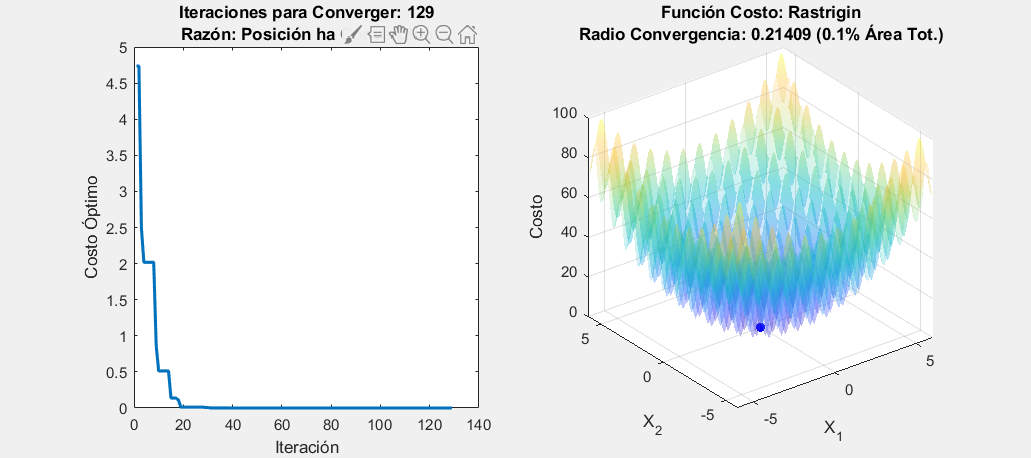

ModoVisualizacion = "3D";                                             % Modo de visualización: 2D, 3D o None. Si se ingresa algo no válido se toma una visualización 3D como default
Iteraciones = 0;
SaveFrames = 1;
j = 0;

if strcmp(ModoVisualizacion, "None") == 0
    figure(1); clf;
    figure('visible','on');
    axis equal; grid on; 
    
    FigureWidth = 900;
    FigureHeight = 400;
    ScreenSize = get(0,'ScreenSize');
    set(gcf, 'Position',  [ScreenSize(3)/2 - FigureWidth/2, ScreenSize(4)/2 - FigureHeight/2, FigureWidth, FigureHeight])
    
    % Graficación de partículas
    subplot(1, 2, 2); 
    
    switch ModoVisualizacion
        case "2D"
            axis([PosMin PosMax PosMin PosMax]);
            PlotSupCosto = contour(MeshX, MeshY, Altura);
            hold on; alpha 0.5;
            PlotParticulas = scatter(Posicion_Actual(:,1), Posicion_Actual(:,2), 10, 'blue', 'filled');
            PlotPuntoMin = scatter(Coords_Min(1), Coords_Min(2), 'red', 'x');
            PlotRadioConv = viscircles(Coords_Min, RadioConvergencia);
        case "3D"
            axis([PosMin PosMax PosMin PosMax MinAltura MaxAltura]);
            PlotSupCosto = surf(MeshX, MeshY, Altura);
            hold on; shading interp; alpha 0.2;
            PlotParticulas = scatter3(Posicion_Actual(:,1), Posicion_Actual(:,2), Costo_Local, [], 'blue', 'filled');
    end
    
    title({"Función Costo: " + CostFunc ; "Radio Convergencia: " + num2str(RadioConvergencia) + " (" + num2str(Porcentaje_AreaTotal) + "% Área Tot.)"});
    xlabel('X_1');
    ylabel('X_2');
    zlabel('Costo');
    
    % Graficación de función de costo
    SubplotCosto = subplot(1, 2, 1);
    PlotCosto = plot(1, Costo_History(1), 'LineWidth', 2);
    title({"Minimización de Función de Costo" ; "Iteraciones Actuales: " + num2str(i)});
    xlabel('Iteración');
    ylabel('Costo Óptimo');
    
    hold off;
    
end

for i = 2:IteracionesMax
    
    R1 = rand([NoParticulas VarDims]);
    R2 = rand([NoParticulas VarDims]);
    Posicion_Previa = Posicion_Actual;
    
    % Actualización de Velocidad
    Velocidad = W * Velocidad ...                                                   % Término inercial
        + C1 * R1 .* (Posicion_LocalBest - Posicion_Actual) ...                     % Componente cognitivo
        + C2 * R2 .* (Posicion_GlobalBest - Posicion_Actual);                       % Componente social
    
    Velocidad = max(Velocidad, VelMin);                                             % Se truncan los valores de velocidad en el valor mínimo y máximo
    Velocidad = min(Velocidad, VelMax);
    
    % Actualización de Posición
    Posicion_Actual = Posicion_Actual + Velocidad;
    Posicion_Actual = max(Posicion_Actual, PosMin);                                 % Se truncan los valores de posición en el valor mínimo y máximo
    Posicion_Actual = min(Posicion_Actual, PosMax);
    
    % Actualización de Local y Global Best
    Costo_Local = CostFunction(Posicion_Actual, CostFunc);                          % Actualización de los valores del costo
    Costo_LocalBest = min(Costo_LocalBest, Costo_Local);                            % Se sustituyen los costos que son menores al "Local Best" previo
    Costo_Change = (Costo_Local < Costo_LocalBest);                                 % Vector binario que indica con un 0 cuales son las filas de "Costo_Local" que son menores que las filas de "Costo_LocalBest"
    Posicion_LocalBest = Posicion_LocalBest .* Costo_Change + Posicion_Actual;      % Se sustituyen las posiciones correspondientes a los costos a cambiar en la linea previa
    
    [Costo_Global, Fila] = min(Costo_LocalBest);                                    % Valor mínimo de entre los valores de "Costo_Local"
    
    if Costo_Global < Costo_GlobalBest                                              % Si el nuevo costo global es menor al "Global Best" entonces
        Costo_GlobalBest = Costo_Global;                                            % Se actualiza el valor del "Global Best"
        Posicion_GlobalBest = Posicion_Actual(Fila, :);                             % Y la posición correspondiente al "Global Best"
    end
    
    % Actualización del historial de "Best Costs"
    Costo_History(i) = Costo_GlobalBest;                                            
    
    % Actualización del coeficiente inercial
    W = W * WDamp;
    
    % Actualizar el número de iteraciones
    Iteraciones = Iteraciones + 1;
    
    switch ModoVisualizacion
        case "2D"
            PlotParticulas.XData = Posicion_Actual(:,1);
            PlotParticulas.YData = Posicion_Actual(:,2);
            PlotCosto.XData = 1:i;
            PlotCosto.YData = Costo_History(1:i);
            
            if Criterios(1) == 1
                set(get(SubplotCosto,'Title'), 'String', {"Condición Alcanzada: " + NomCriterios(1); "Iteraciones Actuales: " + num2str(i)});
            else
                set(get(SubplotCosto,'Title'), 'String', {"Minimización de Función de Costo" ; "Iteraciones Actuales: " + num2str(i)});
            end
            
        case "3D"
            PlotParticulas.XData = Posicion_Actual(:,1);
            PlotParticulas.YData = Posicion_Actual(:,2);
            PlotParticulas.ZData = Costo_Local;
            PlotCosto.XData = 1:i;
            PlotCosto.YData = Costo_History(1:i);
            
            if Criterios(1) == 1
                set(get(SubplotCosto,'Title'), 'String', {"Condición Alcanzada: " + NomCriterios(1); "Iteraciones Actuales: " + num2str(i)});
            else
                set(get(SubplotCosto,'Title'), 'String', {"Minimización de Función de Costo" ; "Iteraciones Actuales: " + num2str(i)});
            end
    end
    
    % Criterios de finalización
    
    Dists_ToMin = sqrt(sum((Posicion_Actual - Coords_Min).^2, 2));                      % Distancias de todas las partículas al mínimo global                       
    Particulas_DentroRadio = sum(Dists_ToMin < RadioConvergencia);                      % Se cuentan todas las partículas cuya distancia al mínimo es menor al radio de convergencia.
    Criterios(1) = Particulas_DentroRadio > Porcentaje_PartDentroRadio*NoParticulas;    % Criterio 1 = Detener si cierto porcentaje de las partículas llega al centro
    Criterios(2) = Criterios(1) * (i > 0.8*IteracionesMax);                             %              Y solo si se ha llegado al 80% de las iteraciones máximas
    
    Dists_ToPrev = sqrt(sum((Posicion_Actual - Posicion_Previa).^2, 2));                % Distancia de la posición actual de cada partícula a su posición previa
    Particulas_Quietas = sum(Dists_ToPrev < Threshold_PosDiff);                         % Se cuentan todas las partículas que se hayan movido una distancia menor a "Threshold_PosDiff"
    Criterios(3) = Particulas_Quietas == NoParticulas;                                  % Criterio 2 = Detener si el número de partículas "quietas" es menor al total de partículas.
    
    Criterios(4) = i == IteracionesMax;                                                 % Criterio 3 = Detener si se llega al número de iteraciones máximo.
    
    if (Criterios(1) && Criterios(2)) || Criterios(3)

        if strcmp(ModoVisualizacion, "None") == 0
            Criterios_Activados = find(Criterios > 0);
            
            if any(Criterios_Activados > 0)
                title({"Iteraciones para Converger: " + num2str(i) ; "Razón: " + NomCriterios(max(Criterios_Activados))});
                break
            end
            
        end
        
    end
    
    % Guardado de Frames Numeradas
    if SaveFrames == 1
        if mod(i,3) == 0
            saveas(gcf, strcat('.\Animation Frames\',CostFunc, ModoVisualizacion,'\',num2str(j),'.png'));
            j = j + 1;
        end
    end
     
    drawnow
     
end